# Estimate Solar Angles and Solar Radiation

Copyright 2024 The MathWorks, Inc.

## Direction Convention

In all calculations in this project, East/West/North/South are defined on a X/Y scale as shown in the picture below. Positive X direction is East, negative X direction is West, Positive Y direction is North, and negative Y direction is South.

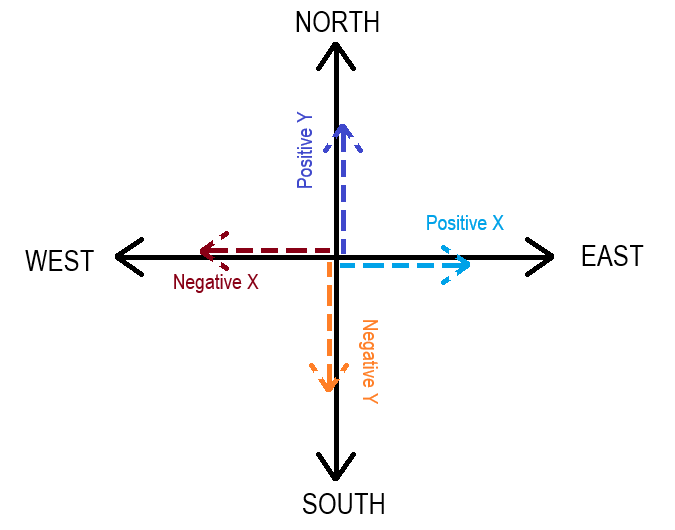

Directionality is specified using a 2-element vector [x,y] representing the direction of the unit vector normal to a flat surface (of interest). For example:

- To specify a south facing surface, you must specify direction as [0, -1]. 

- To specify a east facing surface, you must specify direction as [1,0].

- To specify a NE facing surface, you must specify direction as [1,1].

It is not mandatory to specify a unit vector (as in case of NE example ablove), but it could be a good practice to do so.

## Initialize Parameters

setCalendarYearParameters
dayLightSavingHrs = 0;
fullDayHrs = 1:dayHours;

Specify the year of interest.

year = 2024;

Set geographical location coordinates.

geoLocation = getGeoLocationForMajorCities(CityName="London");

## Analyze Data During Solistice and Equinox  Days

Get solar radiation data for the specified `year` and the four `solsticeEquinoxDays` days.

solarData = getSolarRadiationData(year,...
    solsticeEquinoxDays,fullDayHrs,geoLocation,dayLightSavingHrs);

Plot solar angle data at noon time for the four specified days.

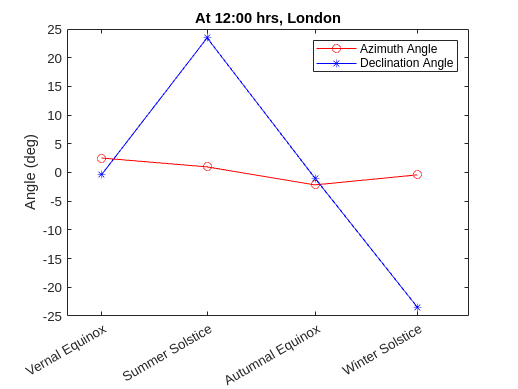

plotSolarAngleDataAtNoon(solarData,geoLocation.Row,...
    solsticeEquinoxDays,solsticeEquinoxDaysLbl);

Plot changes in solar angle across the four specified days.

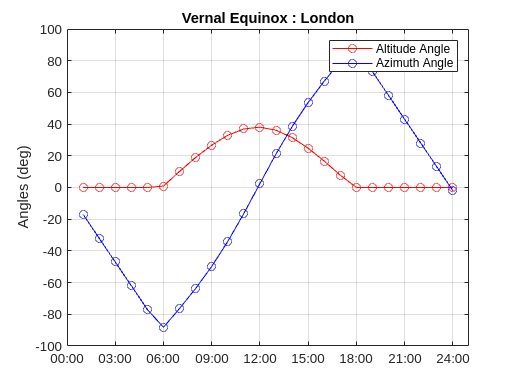

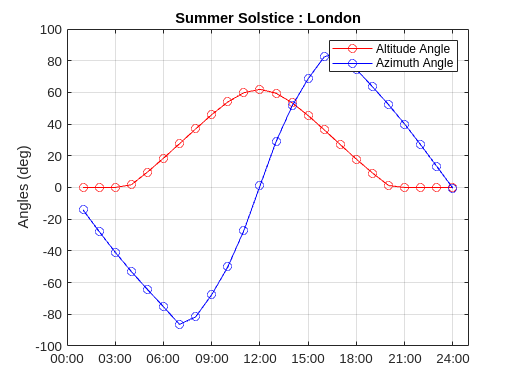

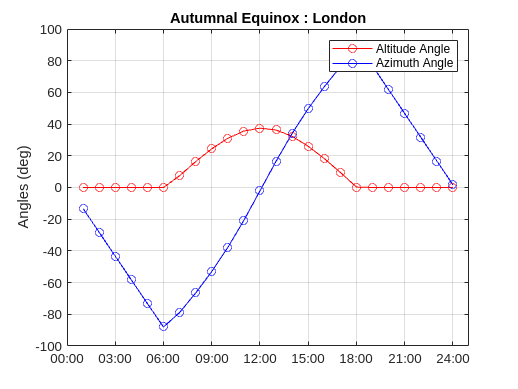

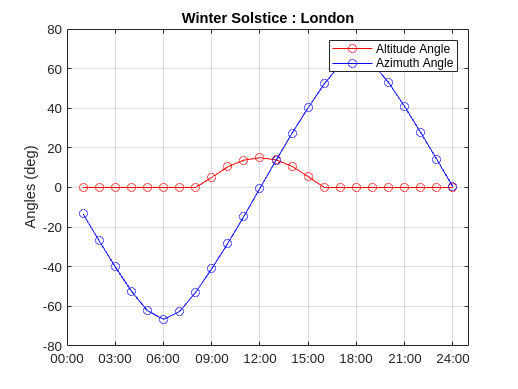

plotDailyChangeOfSolarAngles(solarData,geoLocation.Row,fullDayHrs,...
    solsticeEquinoxDays,solsticeEquinoxDaysLbl);

Plot solar altitude agianst solar azimuth angle.

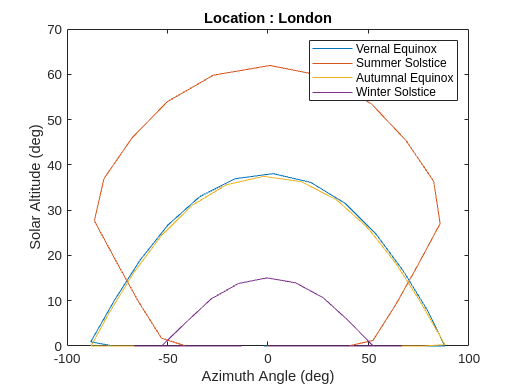

plotSolarAltitudeVsAzimuthAngle(solarData,geoLocation.Row,fullDayHrs,...
    solsticeEquinoxDays,solsticeEquinoxDaysLbl);

## Analyze Annual Data

Analyze data for one full year, at noon time.

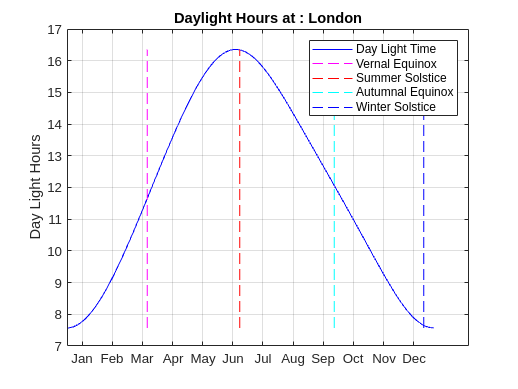

solarData = getSolarRadiationData(year,...
    1:daysYear,fullDayHrs,geoLocation,dayLightSavingHrs);

plotDaylightDurationForLocation(solarData,geoLocation.Row,...
    1:daysYear,solsticeEquinoxDays);

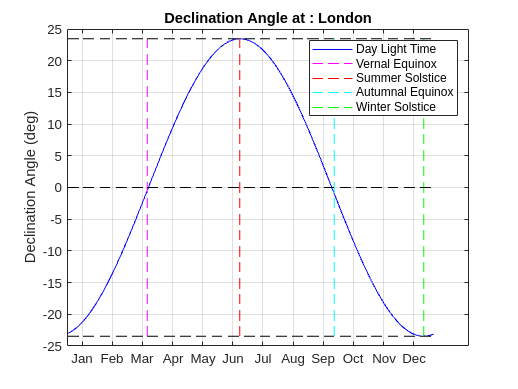


plotDeclinationAngleForLocation(solarData,geoLocation.Row,...
    1:daysYear,solsticeEquinoxDays)

## Radiation Falling On Flat Surface

Specify number of equi-spaced angles of a flat plane, to evalaute data for solar radiation.

numAngles = 3;

Specify direction of flat surface.

dirVector = [0,-1]; % South facing.

Specify the day (number) of the year.

dayOfTheYear = solsticeEquinoxDays(1,2);

Specify day light saving hours, if any, on that day.

dayLightSavingHrs = 0;

Plot data.

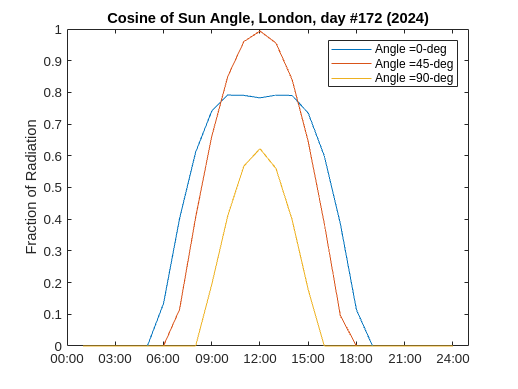

Wall#1::1-1-1 = -0.97       -0.26, pt1=-0.053918    -0.80965, pt2=-0.68502      1.5457
Wall#2::1-1-2 = -0.26        0.97, pt1=-0.68502      1.5457, pt2=0.19822      1.7823
Wall#3::1-2-2 = -0.26        0.97, pt1=1.9436      3.5122, pt2=4.8877      4.3011
Wall#4::1-2-3 = 0.97        0.26, pt1=4.8877      4.3011, pt2=5.9921     0.17928
Wall#5::1-2-4 = 0.26       -0.97, pt1=5.9921     0.17928, pt2=3.048     -0.6096
Wall#6::1-3-1 = -0.97       -0.26, pt1=1.0082     -2.4184, pt2=0.92935     -2.1239
Wall#7::1-3-3 = 0.97        0.26, pt1=3.048     -0.6096, pt2=3.3636     -1.7873
Wall#8::1-3-4 = 0.26       -0.97, pt1=3.3636     -1.7873, pt2=1.0082     -2.4184
Wall#9::1-4-1 = -0.97       -0.26, pt1=0.19822      1.7823, pt2=-0.19622      3.2544
Wall#10::1-4-2 = -0.26        0.97, pt1=-0.19622      3.2544, pt2=1.8647      3.8066
Wall#11::1-4-3 = 0.97        0.26, pt1=1.8647      3.8066, pt2=1.9436      3.5122
Wall#12::1-5-1 = -0.97       -0.26, pt1=-0.24831     -2.4395, pt2=-0.64275    -0.96743
Wa

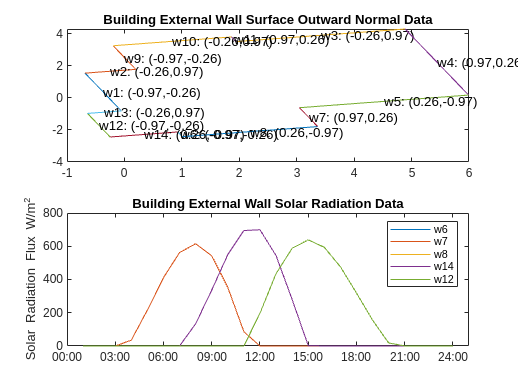

cosineAngleOfIncidence = zeros(1,24);
figure('Name','Angle of Incidence')
angleName = cell(1,numAngles);
for s = 1:numAngles
    slopeFlatSurf = (s-1)*(90/(numAngles-1));
    angleName{1,s} = strcat('Angle = ',num2str(slopeFlatSurf),'-deg');
    for i = 1:24
        cosineAngleOfIncidence(1,i) = getAngleSunRaysOnSurface(...
            slopeFlatSurf,dirVector,year,dayOfTheYear,i,geoLocation,dayLightSavingHrs);
    end
    plot(1:24,cosineAngleOfIncidence); hold on;
end
hold off
title(strcat("Cosine of Sun Angle, ",string(geoLocation.Row),...
    ", day #",num2str(dayOfTheYear)," (",num2str(year),")"));
ylabel('Fraction of Radiation');
timeForPlotting = {'00:00','03:00','06:00','09:00','12:00','15:00','18:00','21:00','24:00'};
xticks(0:3:24); xticklabels(timeForPlotting);
legend(angleName);